clear; clc; close all;

%% === 0. 文件名设置 (请在此处修改为你实际的文件名) ===
file_task2 = '1.s2p';  % 任务2文件: J1-J3 (J2匹配)
file_task3 = '2.s2p'; % 任务3文件: J1-J2 (J3匹配)
file_task4 = '3.s2p';% 任务4文件: J2-J3 (J1匹配)
file_task5 = '4.s2p';     % 任务5文件: J1-J3 (J2悬空)

%% === 1. 读取 S 参数数据 ===
try
    sp2 = sparameters(file_task2);
    sp3 = sparameters(file_task3);
    sp4 = sparameters(file_task4);
    sp5 = sparameters(file_task5);
catch
    error('错误: 无法读取文件。请确保文件名正确且文件在当前路径下，并已安装 RF Toolbox。');
end

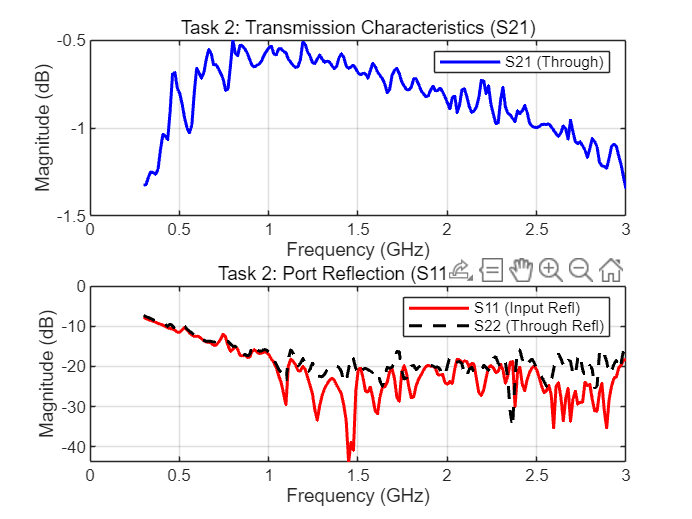


% 提取频率 (假设所有测量频率范围一致)
freq = sp2.Frequencies / 1e9; % 将频率转换为 GHz

%% === 2. 任务2: 传输特性 (S21) 与 端口反射 (S11, S22) ===
% 物理连接: VNA P1->J1, VNA P2->J3. 
% VNA S21 = 耦合器直通 S21
% VNA S11 = J1 反射
% VNA S22 = J3 反射

figure('Name', 'Task 2: Transmission & Reflection (Matched)');
% S21 (传输)
subplot(2,1,1);
data_s21 = 20*log10(abs(rfparam(sp2, 2, 1)));
plot(freq, data_s21, 'b', 'LineWidth', 1.5);
grid on; title('Task 2: Transmission Characteristics (S21)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('S21 (Through)');

% S11, S22 (反射)
subplot(2,1,2);
data_s11 = 20*log10(abs(rfparam(sp2, 1, 1)));
data_s22 = 20*log10(abs(rfparam(sp2, 2, 2)));
plot(freq, data_s11, 'r', 'LineWidth', 1.5); hold on;
plot(freq, data_s22, 'k--', 'LineWidth', 1.5);
grid on; title('Task 2: Port Reflection (S11, S22)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('S11 (Input Refl)', 'S22 (Through Refl)');

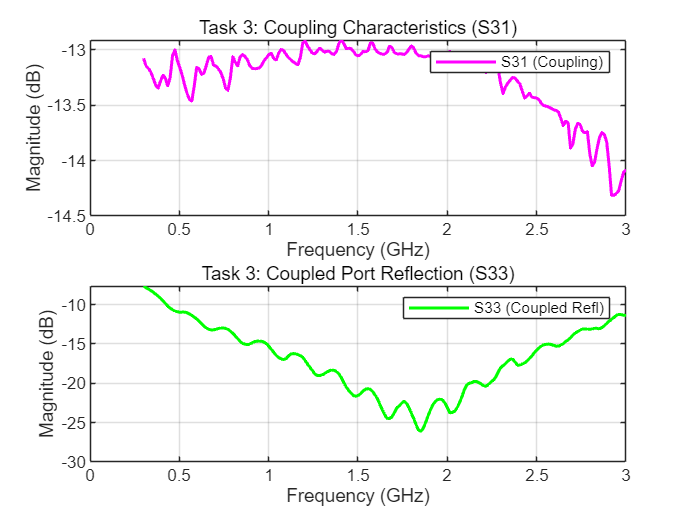


%% === 3. 任务3: 耦合特性 (S31) 与 端口反射 (S33) ===
% 物理连接: VNA P1->J1, VNA P2->J2.
% VNA S21 = 耦合度 (S31)
% VNA S22 = J2 反射 (S33)

figure('Name', 'Task 3: Coupling & Reflection');
% 耦合度
subplot(2,1,1);
data_coup = 20*log10(abs(rfparam(sp3, 2, 1)));
plot(freq, data_coup, 'm', 'LineWidth', 1.5);
grid on; title('Task 3: Coupling Characteristics (S31)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('S31 (Coupling)');

% J2 反射
subplot(2,1,2);
data_s33 = 20*log10(abs(rfparam(sp3, 2, 2)));
plot(freq, data_s33, 'g', 'LineWidth', 1.5);
grid on; title('Task 3: Coupled Port Reflection (S33)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('S33 (Coupled Refl)');

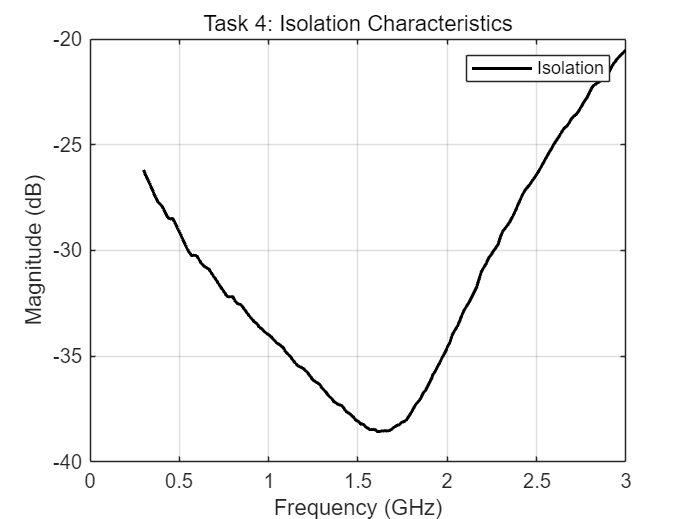


%% === 4. 任务4: 隔离特性 (S41/Isolation) ===
% 物理连接: VNA P1->J2, VNA P2->J3 (J1匹配).
% 注意：根据定义，隔离度通常指输入端到隔离端的泄漏。
% 在你的实验连线中，测得的 VNA S21 代表 J2 和 J3 之间的传输。
% 这里我们将其作为隔离特性的表征进行绘图。

figure('Name', 'Task 4: Isolation');
data_iso = 20*log10(abs(rfparam(sp4, 2, 1)));
plot(freq, data_iso, 'k', 'LineWidth', 1.5);
grid on; title('Task 4: Isolation Characteristics');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('Isolation');

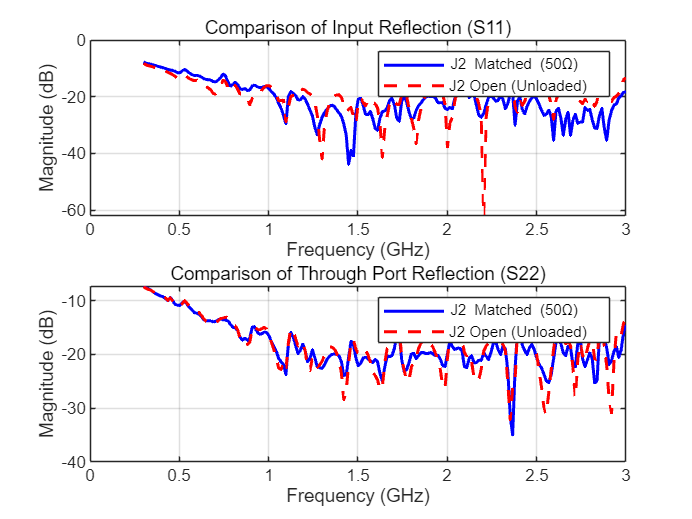


%% === 5. 任务5: 端口反射对比分析 (匹配 vs 悬空) ===
% 对比 Task 2 (J2 匹配) 和 Task 5 (J2 悬空) 的 S11 和 S22

figure('Name', 'Task 5: Reflection Comparison (Matched vs Open)');

% 对比 S11
subplot(2,1,1);
data_s11_open = 20*log10(abs(rfparam(sp5, 1, 1)));
plot(freq, data_s11, 'b', 'LineWidth', 1.5); hold on;
plot(freq, data_s11_open, 'r--', 'LineWidth', 1.5);
grid on; title('Comparison of Input Reflection (S11)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('J2 Matched (50\Omega)', 'J2 Open (Unloaded)');

% 对比 S22
subplot(2,1,2);
data_s22_open = 20*log10(abs(rfparam(sp5, 2, 2)));
plot(freq, data_s22, 'b', 'LineWidth', 1.5); hold on;
plot(freq, data_s22_open, 'r--', 'LineWidth', 1.5);
grid on; title('Comparison of Through Port Reflection (S22)');
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
legend('J2 Matched (50\Omega)', 'J2 Open (Unloaded)');